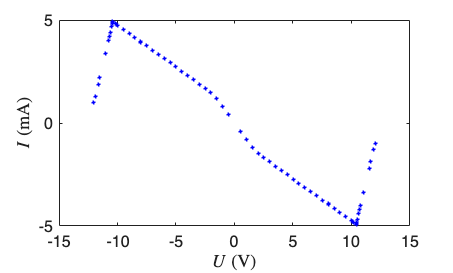

% 假设你的两个表名为 Table_T 和 Table_R
% 假设 T 的列名为 'Temperature'，R 的列名为 'Resistance'

% 1. 提取数值数据为向量
T_data = U.finalU;  % 使用点运算符提取 T 的数据（作为横坐标）
R_data = I.finalI;   % 使用点运算符提取 R 的数据（作为纵坐标）

% 2. 绘制图形
figure; % 打开一个新的绘图窗口
plot(T_data, R_data, 'b+', 'MarkerSize', 3, 'LineWidth', 1); % 蓝色实线和圆圈标记


% 修正后的轴标签（通常没问题，但如果仍然警告，可能也需要检查空格）
xlabel('$U$ (V)', 'Interpreter', 'latex'); 
ylabel('$I$ ($\mathrm{mA}$)', 'Interpreter', 'latex');
% 4. 添加网格线
grid off;

% 5. 设置图表细节（可选）
set(gca, 'FontSize', 12);

clc;

% =================================================================
% 步骤 0: 数据确认
% 假设 T_data 和 R_data 已经在 MATLAB Workspace 中存在。
% =================================================================

% --- 核心参数调整区 (!!! 请根据您的数据曲线手动调整以下参数 !!!) ---
% 1. 正常态线性拟合区域 (例如：转变发生在 10K-20K，正常态区域可选 25K 到 30K)
T_NORMAL_FIT_RANGE = [150, 300]; 

% 2. 偏差阈值 (R_DEVIATION_THRESHOLD)：
%    定义数据点被认为"脱离"拟合线的电阻差值。
%    例如：如果您的仪器精度是 0.01 mOhm，可以将阈值设为 0.05 mOhm。
%    或者，设置为正常态电阻的 0.5% (0.005)
DEVIATION_THRESHOLD_PERCENT = 0.03; % 使用正常态电阻的 0.5% 作为阈值

% 3. 零电阻阈值 (正常态电阻的百分比)
ZERO_THRESHOLD_PERCENT = 0.05; % 1%
% -------------------------------------------------------------------------


% =================================================================
% 步骤 1: 正常态拟合与 R_Normal 确定 (保持不变)
% =================================================================

T_high_temp = max(T_data);
T_low_temp = min(T_data);

% 正常态线性拟合
idx_normal = find(T_data >= T_NORMAL_FIT_RANGE(1) & T_data <= T_NORMAL_FIT_RANGE(2));
T_normal_fit = T_data(idx_normal);
R_normal_fit = R_data(idx_normal);

if length(idx_normal) < 2
    error('正常态拟合区域数据点不足，请增大 T_NORMAL_FIT_RANGE 范围。');
end

% 线性拟合: R(T) = A_normal * T + B_normal
P_normal = polyfit(T_normal_fit, R_normal_fit, 1);
A_normal = P_normal(1);
B_normal = P_normal(2);

% 用于 T_c^zero 计算的 R_Normal 平均值 (使用拟合区域内的平均值)
R_normal_avg = mean(R_normal_fit);


% =================================================================
% 步骤 2: T_c^onset (偏差阈值法) 计算 (重点修改部分)
% =================================================================

% 1. 设定绝对偏差阈值 (R_DEVIATION_THRESHOLD)
R_DEVIATION_THRESHOLD = R_normal_avg * DEVIATION_THRESHOLD_PERCENT;

% 2. 计算所有数据点到正常态拟合线的外推偏差 (R_fit - R_exp)
R_fit_extrapolated = polyval(P_normal, T_data);
R_deviation = R_fit_extrapolated - R_data; 

% 3. 查找第一个明显偏离的点 (从高 T 到低 T 搜索)
%   - 偏离的条件：偏差 R_deviation > R_DEVIATION_THRESHOLD
%   - 我们只关心低于正常态温度的区域，因此限制 T_data < T_high_temp
idx_deviation = find(T_data < T_high_temp & R_deviation > R_DEVIATION_THRESHOLD);

if isempty(idx_deviation)
    warning('未发现明显偏离正常态拟合线的点，T_c^onset可能无法准确确定。');
    Tc_onset = NaN; 
else
    % Tc_onset 是在满足偏离条件的点中对应的最高温度
    Tc_onset = max(T_data(idx_deviation));
    R_onset_value = polyval(P_normal, Tc_onset);
end


% =================================================================
% 步骤 3: T_c^zero (零电阻温度) 计算 (保持不变)
% =================================================================

R_zero_threshold = R_normal_avg * ZERO_THRESHOLD_PERCENT; 
zero_R_indices = find(R_data <= R_zero_threshold);

if isempty(zero_R_indices)
    Tc_zero = T_low_temp;
else
    Tc_zero = max(T_data(zero_R_indices)); 
end

Tc_zero = 89.72

% =================================================================
% 步骤 4: 绘图与标记
% =================================================================

figure('Color', 'w'); 

plot(T_data, R_data, 'ko', 'MarkerFaceColor', [0.5 0.5 0.5], 'MarkerSize', 5, 'DisplayName', '实验数据');                  
hold on; 

% 绘制正常态拟合线的外推 (从最低温度一直延伸)
T_plot_extrapolate = linspace(T_low_temp, T_high_temp * 1.05, 100);
R_normal_extrapolate = polyval(P_normal, T_plot_extrapolate);
plot(T_plot_extrapolate, R_normal_extrapolate, 'g-', 'LineWidth', 1.5, 'DisplayName', '$\mathrm{R}_{\mathrm{Normal}}$ 拟合 (外推)');


% --- 标记 T_c^onset 和 T_c^zero ---

% 1. 标记 T_c^onset (第一个明显脱离拟合线的点)
if ~isnan(Tc_onset)
    plot(Tc_onset, R_data(T_data == Tc_onset), 'bx', 'MarkerSize', 10, 'LineWidth', 2); % 偏离点标记
    plot([Tc_onset, Tc_onset], [0, R_normal_avg * 1.05], 'b--', 'LineWidth', 1, 'DisplayName', '$\mathrm{T}_{\mathrm{c}}^{\mathrm{onset}}$');

    text(Tc_onset - 2, R_normal_avg * 0.9, ...
         ['$T_{\mathrm{c}}^{\mathrm{onset}} = ', num2str(Tc_onset, '%.2f'), '\mathrm{ K}$'], ...
         'Interpreter', 'latex', 'Color', 'b', 'FontSize', 10);
end

% 2. 标记 T_c^zero
plot([Tc_zero, Tc_zero], [0, R_normal_avg * 1.05], 'r--', 'LineWidth', 1, 'DisplayName', '$\mathrm{T}_{\mathrm{c}}^{\mathrm{zero}}$');
text(Tc_zero + 0.5, R_normal_avg * 0.7, ...
     ['$T_{\mathrm{c}}^{\mathrm{zero}} = ', num2str(Tc_zero, '%.2f'), '\mathrm{ K}$'], ...
     'Interpreter', 'latex', 'Color', 'r', 'FontSize', 10);


% --- 标题和标签设置 ---
xlabel({'$T$ (K)'}, 'Interpreter', 'latex', 'FontSize', 12); 
ylabel({ '$R$ ($\mathrm{m\Omega}$)'}, 'Interpreter', 'latex', 'FontSize', 12); 

% --- 图表美化 ---
legend('Location', 'best', 'Interpreter', 'latex', 'FontSize', 10);
grid off;
box on;
xlim([T_low_temp * 0.9, T_high_temp * 1.05]);
ylim([min(0, min(R_data)*0.9), max(R_data)*1.05]); 

hold off;

